# MECH 6318 - Homework 10

Name: Jonas Wagner

Date: 2021-12-08

clear
close all

## Problem Definition

c = [5;
     8];
A = [1,  1;
     5,  9];
b = [ 6;
     45];



## Problem 14.3 - Branch and Bound

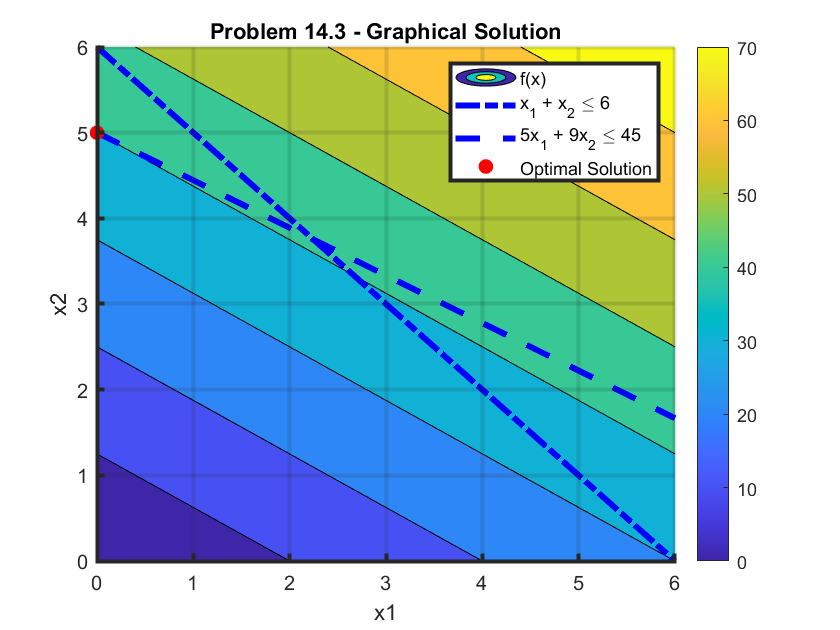

x1 = linspace(0, 6);
x2 = linspace(0, 6);
[X1, X2] = meshgrid(x1, x2);

F = c(1) * X1 + c(2) * X2;
c1 = @(x1) (b(1) - A(1,1)*x1)/A(1,2);
c2 = @(x1) (b(2) - A(2,1)*x1)/A(2,2);

xstar = [0; 5];

figure()
hold on
grid on
contourf(X1,X2,F,...
    'DisplayName', 'f(x)')
plot(x1, c1(x1), 'b-.',...
    'LineWidth', 3,...
    'DisplayName', 'x_1 + x_2 \leq 6')
plot(x1, c2(x1), 'b--',...
    'LineWidth', 3,...
    'DisplayName', '5x_1 + 9x_2 \leq 45')
plot(xstar(1), xstar(2), 'r.', ...
    'MarkerSize', 25,...
    'DisplayName','Optimal Solution')
legend
colorbar
ax = gca;
ax.Layer = 'top';
ax.LineWidth = 2;
title('Problem 14.3 - Graphical Solution')
xlabel('x1')
ylabel('x2')

## Problem 14.6 - Relaxed Constraint Method

opt = @(x) - (c(1) * x(1) + c(2) * x(2))

opt = function_handle with value:
    @(x)-(c(1)*x(1)+c(2)*x(2))



x0 = [0; 0];
% A = A;
% b = b;
Aeq = [];
beq = [];
lb = [0; 0];
ub = [];

[xstar, fstar] = fmincon(opt,x0,A,b,Aeq,beq,lb,ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


xstar =     2.2500
    3.7500


fstar = -41.2500


xstar_int = [floor(xstar), ceil(xstar)];


### Branch Testing

% Opt Problem Solution
opt_pblm = @(x0,lb,ub) fmincon(opt,x0,A,b,Aeq,beq,lb,ub);


#### Branch 1 -  $x_1 \leq 2$

x0 = [0, 0];
lb = [0, 0];
ub = [2, inf];
[Xstar(:,1), Fval(1)] = opt_pblm(x0,lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


#### Branch 2 -  $x_1 \leq 2$ & $x\leq 3$

x0 = [2, 3];
lb = [0, 0];
ub = [2, 3];
[Xstar(:,2), Fval(2)] = opt_pblm(x0,lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


#### Branch 3 -  $x_1 \leq 2$ & $x\geq 4$

x0 = [2, 4];
lb = [0, 4];
ub = [2, inf];
[Xstar(:,3), Fval(3)] = opt_pblm(x0,lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


#### Branch 4 - $x_1 \leq 1$ & $x \geq 4$

x0 = [2, 4];
lb = [0, 4];
ub = [1, inf];
[Xstar(:,4), Fval(4)] = opt_pblm(x0,lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


#### Branch 5 - $x_1 \leq 1$ & $x \geq 5$

x0 = [2, 4];
lb = [0, 5];
ub = [1, inf];
[Xstar(:,5), Fval(5)] = opt_pblm(x0,lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


#### Branch 6 -  $x_1 \geq 3$

x0 = [3, 0];
lb = [3, 0];
ub = [inf, inf];
[Xstar(:,6), Fval(6)] = opt_pblm(x0,lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


#### Branch 7 -  $x_1 \geq 3$ & $x\geq 3$ (not needed...)

x0 = [3, 4];
lb = [3, 3];
ub = [inf, inf];
[Xstar(:,7), Fval(7)] = opt_pblm(x0,lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


#### Branch 7 -  $x_1 \geq 3$ & $x\leq 3$ (not needed...)

x0 = [3, 3];
lb = [3, 0];
ub = [inf, 3];
[Xstar(:,8), Fval(8)] = opt_pblm(x0,lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>






results = table(Xstar(1,:)',Xstar(2,:)', Fval',...
    'VariableNames',{'x_1','x_2','f(x_1,x_2)'})

results = 8×3 table
       x_1         x_2      f(x_1,x_2)
    __________    ______    __________

             2    3.8889     -41.111  
             2         3         -34  
           1.8         4         -41  
             1    4.4444     -40.556  
    3.6455e-07         5         -40  
             3         3         -39  
             3         3         -39  
             3         3         -39  


Clearly this implies the solution is branch 5 which is the smallest function value with a feasabel integer solution. Therefore, the solution to the original maximization problem is:

xstar = [0; 5]

xstar =      0
     5


fstar = -opt(xstar)

fstar = 40

## Problem 14.9 - Cutting Plane

#### Simplex Table

syms f
T = [[A, eye(size(A,1)), b];...
    [-c',zeros(1,size(A,1)),f]]

$$T = \left(\begin{array}{ccccc} 1 & 1 & 1 & 0 & 6\\ 5 & 9 & 0 & 1 & 45\\ -5 & -8 & 0 & 0 & f \end{array}\right)$$

#### Simplex Relaxed Solution

R1 = T(1,:);
R2 = T(2,:);
R3 = T(3,:);

R2 = R2/R2(2);
T1 = [R1; R2; R3]

$$T1 = \left(\begin{array}{ccccc} 1 & 1 & 1 & 0 & 6\\ \frac{5}{9} & 1 & 0 & \frac{1}{9} & 5\\ -5 & -8 & 0 & 0 & f \end{array}\right)$$


R1 = R1 - R2(2)*R2;
R3 = R3 - R3(2)*R2;
T2 = [R1; R2; R3]

$$T2 = \left(\begin{array}{ccccc} \frac{4}{9} & 0 & 1 & -\frac{1}{9} & 1\\ \frac{5}{9} & 1 & 0 & \frac{1}{9} & 5\\ -\frac{5}{9} & 0 & 0 & \frac{8}{9} & f+40 \end{array}\right)$$


R1 = R1/R1(1);
T3 = [R1; R2; R3]

$$T3 = \left(\begin{array}{ccccc} 1 & 0 & \frac{9}{4} & -\frac{1}{4} & \frac{9}{4}\\ \frac{5}{9} & 1 & 0 & \frac{1}{9} & 5\\ -\frac{5}{9} & 0 & 0 & \frac{8}{9} & f+40 \end{array}\right)$$


R2 = R2 - R2(1)*R1;
R3 = R3 - R3(1)*R1;
T4 = [R1; R2; R3]

$$T4 = \left(\begin{array}{ccccc} 1 & 0 & \frac{9}{4} & -\frac{1}{4} & \frac{9}{4}\\ 0 & 1 & -\frac{5}{4} & \frac{1}{4} & \frac{15}{4}\\ 0 & 0 & \frac{5}{4} & \frac{3}{4} & f+\frac{165}{4} \end{array}\right)$$

#### Cutting Plane

We have


$$x_1 = \frac{1}{4}(9 -  9 s_1 + s_2)$$


Which implies


$$x_1 + 2 s_1 -2 = \frac{1}{4}(1 - s_1 + s_2)$$


Therefore


$$\frac{1}{4}(-s_1 + s_2) \leq -\frac{1}{4} $$


which implies


$$-s_1 + s_2 \leq -1$$


Adding in the new slack variable $s_3$ we have:


$$-s_1 + s_2 + s_3 \leq -1$$


#### New Table

R1 = [T4(1,1:4),  0, T4(1,end)];
R2 = [T4(2,1:4),  0, T4(2,end)];
R3 = [0, 0, 1, 1, 1, 1];
R4 = [T4(3,1:4),  0, T4(end,end)];
T5 = [R1; R2; R3; R4]

$$T5 = \left(\begin{array}{cccccc} 1 & 0 & \frac{9}{4} & -\frac{1}{4} & 0 & \frac{9}{4}\\ 0 & 1 & -\frac{5}{4} & \frac{1}{4} & 0 & \frac{15}{4}\\ 0 & 0 & 1 & 1 & 1 & 1\\ 0 & 0 & \frac{5}{4} & \frac{3}{4} & 0 & f+\frac{165}{4} \end{array}\right)$$

#### Final Table

R1 = R1 - R1(3)*R3;
R2 = R2 - R2(3)*R3;
R4 = R4 - R4(3)*R3;
T6 = [R1; R2; R3; R4]

$$T6 = \left(\begin{array}{cccccc} 1 & 0 & 0 & -\frac{5}{2} & -\frac{9}{4} & 0\\ 0 & 1 & 0 & \frac{3}{2} & \frac{5}{4} & 5\\ 0 & 0 & 1 & 1 & 1 & 1\\ 0 & 0 & 0 & -\frac{1}{2} & -\frac{5}{4} & f+40 \end{array}\right)$$

Which results in the following solution:

xstar = [0, 5]'

xstar =      0
     5


fval = -opt(xstar)

fval = 40